N = 10000000;
prob1 = [0.7, 0.29, 0.01];
alphabet1 = 1 : 3;
chain1 = randsrc(1,N, [alphabet1; prob1]);

alphabet2 = 1 : 9;
prob2 = kron(prob1,prob1);
chain2 = randsrc(1,N, [alphabet2; prob2]);

alphabet3 = 1 : 27;
prob3 = kron(prob1,prob2);
chain3 = randsrc(1,N, [alphabet3; prob3]);

K = 1:10;
G1 = zeros(1,length(K));
G2 = zeros(1,length(K));
G3 = zeros(1,length(K));
average_length1 = zeros(1,length(K));
average_length2 = zeros(1,length(K));
average_length3 = zeros(1,length(K));
HN1 = zeros(1, length(K));
HN2 = zeros(1, length(K));
HN3 = zeros(1, length(K));

for i=1:length(K)
    G1(i) = entropy_memless(prob1,i);
    G2(i) = entropy_memless(prob2,i);
    G3(i) = entropy_memless(prob3,i);
    average_length1(1,i) = average_length(chain1, i);
    average_length2(1,i) = average_length(chain2, i);
    average_length3(1,i) = average_length(chain3, i);
    HN1(1,i) = average_length1(1,i)/i;
    HN2(1,i) = average_length2(1,i)/i;
    HN3(1,i) = average_length3(1,i)/i;
end
HX1 = G1(1)/2; 
HX2 = G2(1)/2;
HX3 = G3(1)/2;

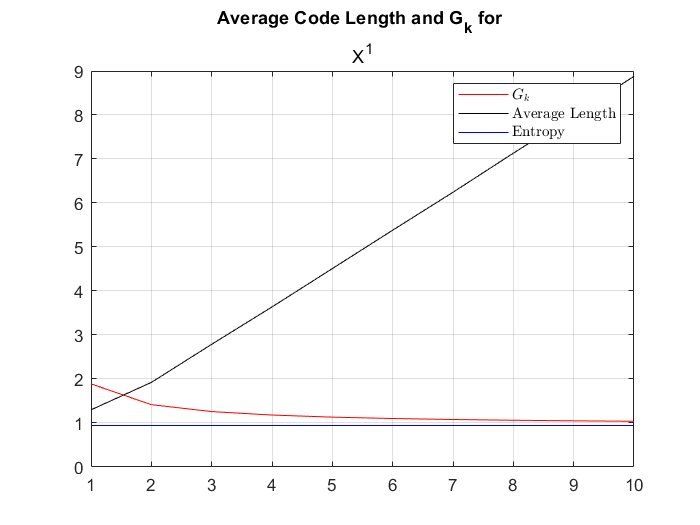

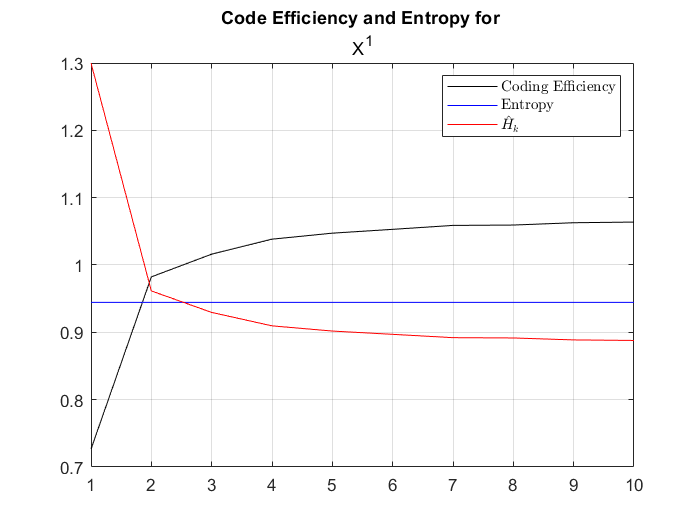

plot_memless(G1,HX1,HN1,K,average_length1,'X^1')

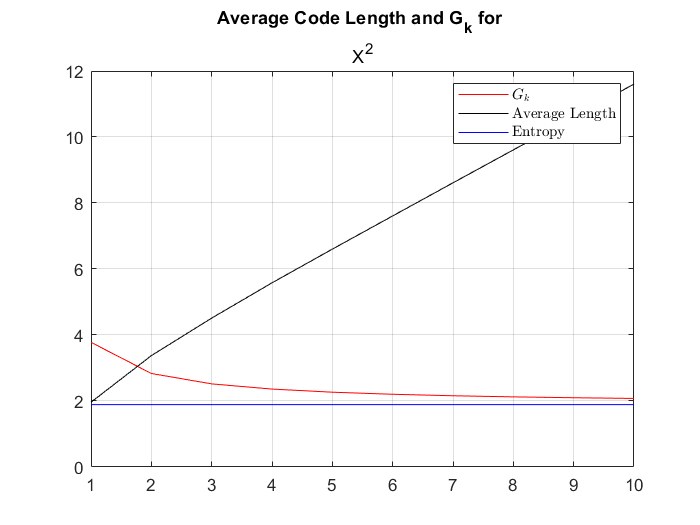

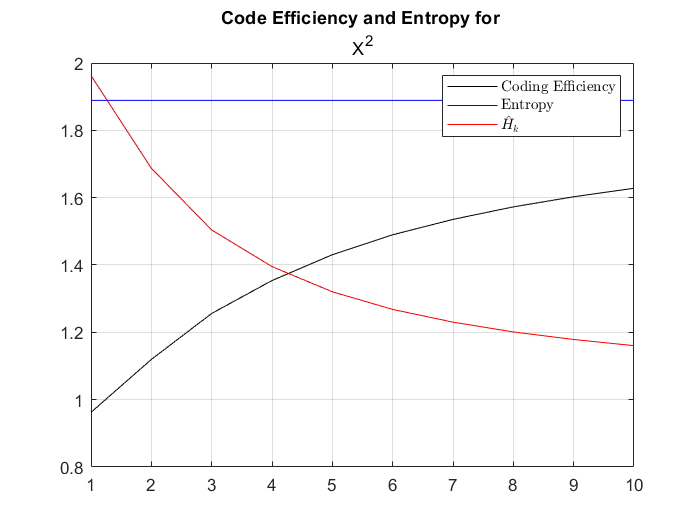

plot_memless(G2,HX2,HN2,K,average_length2,'X^2')

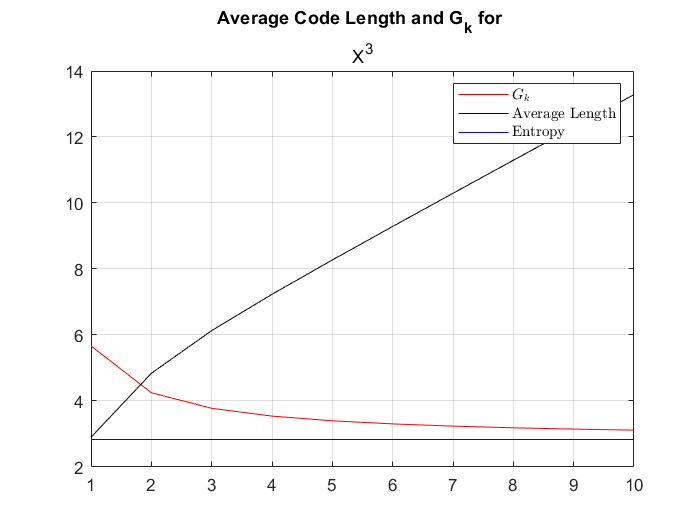

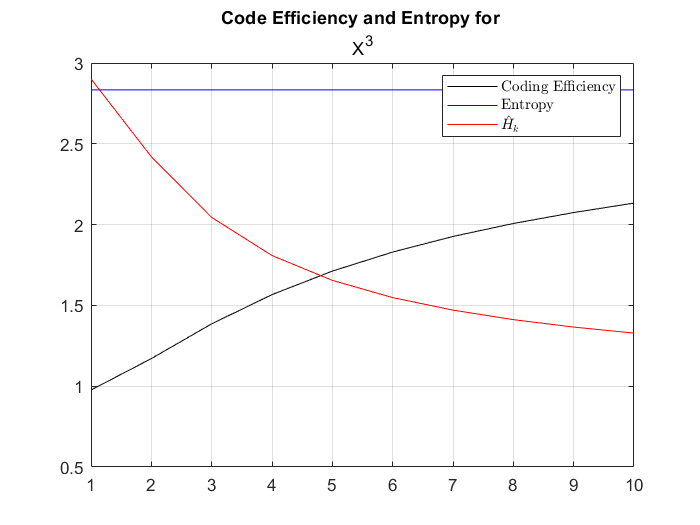

plot_memless(G3,HX3,HN3,K,average_length3,'X^3')

function [average_length_huffman] = average_length(chain , k)
%step1: make super-symbol with k-bit groups
res = mod(length(chain),k);
len = length(chain) - res;
normalize_chain = zeros(1, len);
for i = 1:(len)
   normalize_chain(1,i) = chain(1,i);
end
group_num = length(normalize_chain)/k;
group_chain = reshape(normalize_chain, [k group_num]);
%step2: assigning symbols to k-bit sequences
symbol_chain = zeros(1, group_num);
for i = 1:group_num
    separate_chain = group_chain(:,i);
        symbol = 0;
    for j = 1:k
        symbol = symbol + separate_chain(j) * 2^(j);
    end
    symbol_chain(1,i) = symbol;
end
%step3: calculating symbol occurance probability
symbols = unique(symbol_chain);
symbol_count = histc(symbol_chain, symbols); 
symbol_probability = zeros(1, length(symbols));
for i = 1 : length(symbols)
    symbol_probability(1,i) = symbol_count(1, i) /length(symbol_chain);
end
%step4: using huffmandict to find average length
[~,average_length_huffman] = huffmandict(symbols,symbol_probability) ;
end

function[Gk] = entropy_memless(prob_symbol,k)
Hx = 0;
for i =1:length(prob_symbol)
    Hx = Hx - prob_symbol(i) *log2(prob_symbol(i));
end
Gk = (k+1)/k * Hx;
end

function plot_memless(G,Hx,HN,K,average_length_huffman,name)
H = zeros(1,length(K)); 
for i = 1:length(H)
    H(1,i) = Hx;
end
code_efficiency = zeros(1,length(K));
for i = 1:length(code_efficiency)
    code_efficiency(1,i) = H(1,i) / (HN(1,i));
end

figure
plot(K,G,'r');
hold on ;
plot(K,average_length_huffman,'black');
hold on 
plot(K,H,'b');
title('Average Code Length and G_k for ', name);
legend({'$G_k$','Average Length','Entropy'},'Interpreter','latex')
grid on;
hold off
figure
plot(K,code_efficiency,'black');
hold on ;
plot(K,H,'b');
hold on ;
plot(K, HN,'r');
title('Code Efficiency and Entropy for ', name);
legend({'Coding Efficiency','Entropy','$\hat{H}_k$'},'Interpreter','latex')
grid on;
end